# A Estimation curve VS different S_EI:L6 added

## first, setup connctivity map

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision-2Drive'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])

load('NtWk_Archit.mat')

## Variables and Parameters

fixed parameters

p_EEFail = 0.2; S_amb = 0.01;
rE_amb = 0.500; rI_amb = 0.500;

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms

gL_E = 1/20;  Ve = 14/3; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

NW Connectivity and L6 Input

S_EE = 0.024; S_EI = S_EE*1.5;  
S_II = 0.120; S_IE = S_II*0.153;
% L6 input
S_EL6 = 1/3*S_EE; S_IL6 = 1/3*S_IE;
rE_L6 = 0.25;     rI_L6 = rE_L6*3; %250hz for now

Make up LGN

S_Elgn = 2*S_EE;
S_Ilgn = 2*S_Elgn;
lambda_E = 0.08; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.08; 

## Network Simulation

S_EE = 0.024, S_EI = 0.036, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

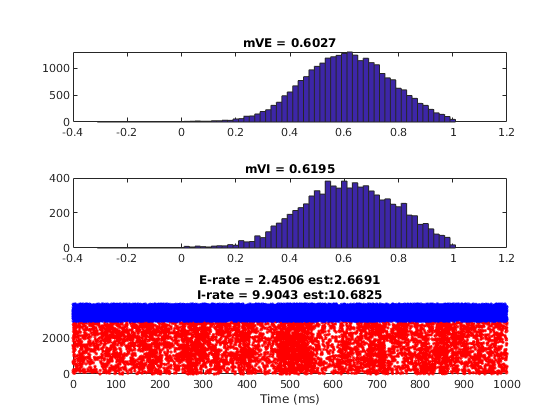

S_EE = 0.024, S_EI = 0.036, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

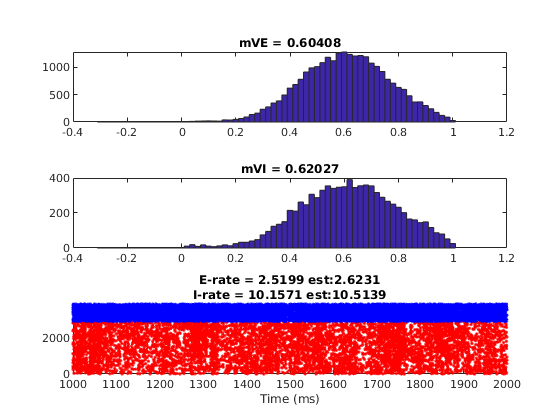

S_EE = 0.024, S_EI = 0.036, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

%% Network Simulation
T = 3000; SimulationT = 1000; dt = 0.1;
% E-to-E delay time
T_EEDly = 0.3; N_EEDly = floor(T_EEDly/dt);
% Setup Results Recording
Fr_NW_BG      = zeros(2,1);
mV_NW_BG      = zeros(2,1);
%Fr_OneStep = zeros(2,EITestN,length(S_IEtest)); % one step MF estimation using network mV

% Compute Neuron Ind
E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
[E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);

I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
[I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);

N_EE = mean(sum(C_EE(E_Ind,:),2)); N_EI = mean(sum(C_EI(E_Ind,:),2));
N_IE = mean(sum(C_IE(I_Ind,:),2)); N_II = mean(sum(C_II(I_Ind,:),2));

% Create sliding windows
sampleT = 20;
Sliding = 5;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);

% The initial states
InSs = load('Initials_L6.mat');
RefTimeE = InSs.RefTimeE; VE = InSs.VE; SpE = InSs.SpE; GE_ampa_R = InSs.GE_ampa_R; GE_nmda_R = InSs.GE_nmda_R; GE_gaba_R = InSs.GE_gaba_R;
GE_ampa_D = InSs.GE_ampa_D; GE_nmda_D = InSs.GE_nmda_D; GE_gaba_D = InSs.GE_gaba_D;
RefTimeI = InSs.RefTimeI; VI = InSs.VI; SpI = InSs.SpI; GI_ampa_R = InSs.GI_ampa_R; GI_nmda_R = InSs.GI_nmda_R; GI_gaba_R = InSs.GI_gaba_R;
GI_ampa_D = InSs.GI_ampa_D; GI_nmda_D = InSs.GI_nmda_D; GI_gaba_D = InSs.GI_gaba_D;
EEDlyRcd = sparse(N_E,N_EEDly);

%E_SpHis= []; I_SpHis=[];
E_Sp = []; I_Sp = [];
VE_T = []; VI_T = [];
sampleN = floor(Sliding/dt); % sample each 2 ms
SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('FrEs',   zeros(size(Wins(:,1))), 'FrIs',   zeros(size(Wins(:,1))),...
    'mVEs',   zeros(size(Wins(:,1))), 'mVIs',   zeros(size(Wins(:,1))));
NWTrace.VEDist =  cell(size(Wins(:,1)));
NWTrace.VIDist =  cell(size(Wins(:,1)));
NWTrace.Wins = Wins;

tic
for TimeN = 1:floor(T/dt)
    [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
        oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
        oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
        oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
        oEEDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
        V1NetworkUpdate_Ver2_EEDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
        GE_ampa_D,GE_nmda_D,GE_gaba_D,...
        RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
        GI_ampa_D,GI_nmda_D,GI_gaba_D,...
        EEDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
        C_EE,C_EI,C_IE,C_II,...
        S_EE,S_EI,S_IE,S_II,...
        tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
        dt,p_EEFail,...
        gL_E,Ve,S_Elgn,rhoE_ampa,rhoE_nmda,...
        gL_I,Vi,S_Ilgn,rhoI_ampa,rhoI_nmda,...
        S_amb,lambda_E,lambda_I,rE_amb,rI_amb,...
        S_EL6,S_IL6,rE_L6,rI_L6); % L6 Parameters          % The lower/upper bounds for kick waiting time
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd;
    
    % When reaching every 500ms, demostrate and pause
    if mod(TimeN,SimulationN) == 0 && TimeN*dt>=400
        ParameterDisp = ['S_EE = ' num2str(S_EE) ', S_EI = ' num2str(S_EI) ...
            ', S_IE = ' num2str(S_IE) ', S_II = ' num2str(S_II) '\n' ...
            'S_Elgn = ' num2str(S_Elgn) ', lambda_E = ' num2str(lambda_E) ...
            ', S_Ilgn = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
            'S_amb = ' num2str(S_amb) ', rE_amb = ' num2str(rE_amb) ', rI_amb = ' num2str(rI_amb)];
        
        fprintf(ParameterDisp)
        h = figure('Name','TestRaster');
        subplot 311
        hist(oVE,-0.3:0.02:1)
        title(['mVE = ' num2str(nanmean(VE_T))])
        %E_SpHis = [E_SpHis,sum(oSpE)];
        %axis([-0.4 1.1 0 6000])
        
        subplot 312
        hist(oVI,-0.3:0.02:1)
        title(['mVI = ' num2str(nanmean(VI_T))])
              
        %E_Ind = 10000:13000; I_Ind = 3300:4300;
        scatterE = find(ismember(E_Sp(:,1),E_Ind));
        scatterI = find(ismember(I_Sp(:,1),I_Ind));
        [~,E_Fire_Ind] = ismember(E_Sp(scatterE,1),E_Ind);
        [~,I_Fire_Ind] = ismember(I_Sp(scatterI,1),I_Ind);
        
        WinSize = SimulationT;
        T_RateWindow = [TimeN*dt-WinSize TimeN*dt];
        E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
        I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        E_Rate = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
        I_Rate = length(I_SpInd)/(WinSize/1000)/length(I_Ind);
        
        f_EnIOneStep = MeanFieldEst_BkGd_L6_OneStep(N_EE,N_EI,N_IE,N_II,...
                                                    S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                                    lambda_E,S_Elgn,rE_amb,S_amb,...
                                                    lambda_I,S_Ilgn,rI_amb,...
                                                    S_EL6,S_IL6,rE_L6,rI_L6,...
                                                    gL_E,gL_I,Ve,Vi,nanmean(VE_T),nanmean(VI_T));
        %
        subplot 313
        hold on
        scatter(E_Sp(scatterE,2),E_Fire_Ind,'r.')
        scatter(I_Sp(scatterI,2),I_Fire_Ind+max(E_Fire_Ind),'b.');
        title({['E-rate = ' num2str(E_Rate) ' est:' num2str(f_EnIOneStep(1))],['I-rate = ' num2str(I_Rate) ' est:' num2str(f_EnIOneStep(2))]})
        xlabel('Time (ms)')
        xlim(T_RateWindow)
        ylim([0 max(I_Fire_Ind)+max(E_Fire_Ind)])
        drawnow
        %pause
        close(h)
        % end of 500ms plot
    end
    
    % every 20ms time window
    if mod(TimeN,sampleN) == 0 && TimeN >= floor(sampleT/dt)
        WinSize = NWTrace.Wins(SampleInd,2) - NWTrace.Wins(SampleInd,1);
        T_RateWindow = NWTrace.Wins(SampleInd,:);
        E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
        I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        
        NWTrace.FrEs(SampleInd) = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
        NWTrace.FrIs(SampleInd) = length(I_SpInd)/(WinSize/1000)/length(I_Ind);
        NWTrace.mVEs(SampleInd) = nanmean(oVE(E_Ind));
        NWTrace.mVIs(SampleInd) = nanmean(oVI(I_Ind));
        
        NWTrace.VEDist{SampleInd} = oVE(E_Ind);
        NWTrace.VIDist{SampleInd} = oVI(I_Ind);
        
        SampleInd = SampleInd + 1;
    end
    
    E_Sp = [E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]];
    I_Sp = [I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]];
    VE_T = [VE_T;nanmean(oVE(E_Ind))];
    VI_T = [VI_T;nanmean(oVI(I_Ind))];
    
    if sum(isnan(oVE))>0.80*N_E
        BlowUp = true;
        disp('warning!: Network exploded')
        break
    end
    
    % the end of iteration
end

toc

Elapsed time is 95.175897 seconds.



NWTrace.E_Sp = E_Sp; NWTrace.I_Sp = I_Sp;


% If blown up, discard other recordings...
if ~BlowUp
    Fr_NW_BG     = [E_Rate;I_Rate];
    mV_NW_BG     = [nanmean(VE_T),nanmean(VI_T)];
    %Fr_OneStep(:,S_EIInd,S_IEInd) = f_EnIOneStep;
end
% end of S_IE loop



## Now, with drive

First figure out orientation domains

ODNum = 4; % 4 orientation domains
% A function from Neuron Ind and spatial scales to Orientation Domains
OD_E = zeros(size(NnE.X));
OD_EMap = zeros(n_E_HC*N_HC);
for NeuInd = 1:length(NnE.X)
OD_E(NeuInd) = OrientDom(ODNum,NnE.X(NeuInd),NnE.Y(NeuInd),n_E_HC);
OD_EMap(NnE.Y(NeuInd),NnE.X(NeuInd)) = OD_E(NeuInd);
end

OD_I = zeros(size(NnI.X));
OD_IMap = zeros(n_I_HC*N_HC);
for NeuInd = 1:length(NnI.X)
OD_I(NeuInd) = OrientDom(ODNum,NnI.X(NeuInd),NnI.Y(NeuInd),n_I_HC);
OD_IMap(NnI.Y(NeuInd),NnI.X(NeuInd)) = OD_I(NeuInd);
end

Then make a transfer between neurons in HCs and 10*10 pixels